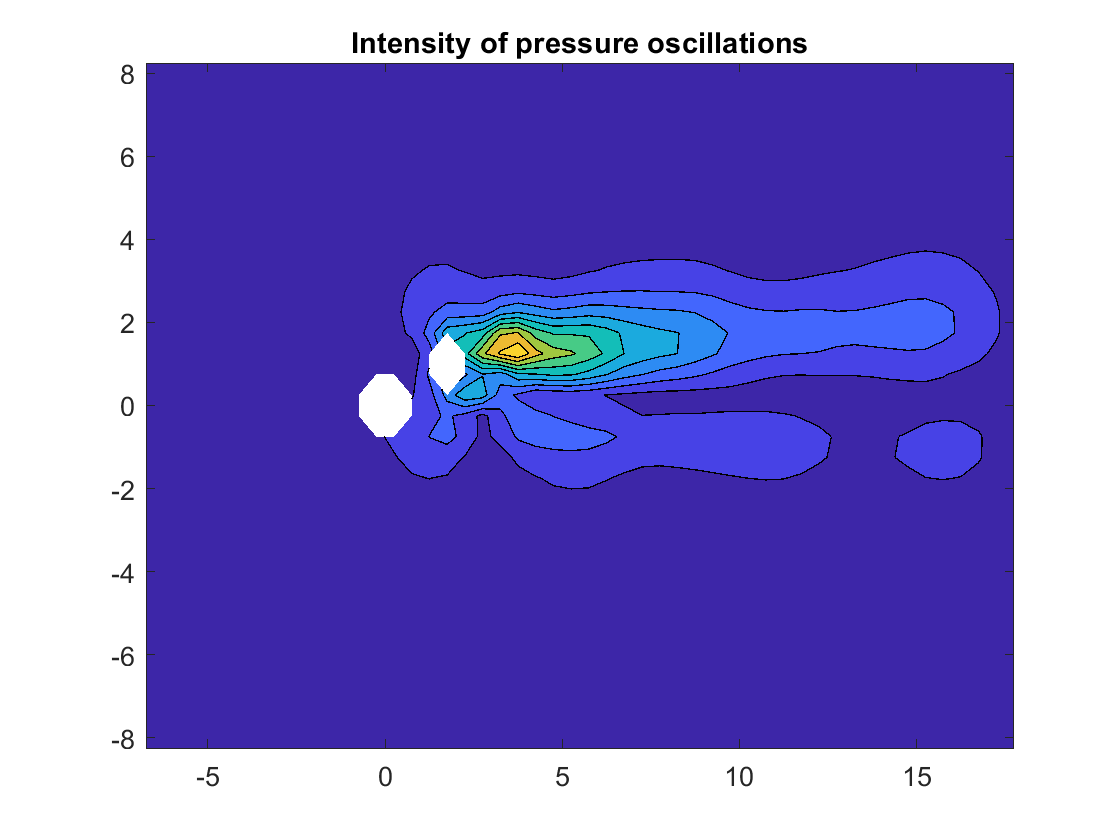

clear; close all

data = load('p_Re_300_gridx_50_gridy_34.txt');
x = data(:,1);
y = data(:,2);
p = data(:,3:end);

% geometry
D = 0.1;
W = 25*D;
H = 17*D;
L_rat = 2;
L = L_rat*D;
CX = 5*D+L;
% 2nd cylinder
D_rat = 1;
d = D_rat*D;
alpha = 30; %deg
D_avg = (d+D)/2;
% flow
Re = 300;
rho = 1000;
mu = 1e-3;
U = Re*mu/(rho*D_avg);
% timestep
St_guess = 0.5;
f_guess = St_guess*U/D_avg;
T_guess = 1/f_guess;
N = 10;
deltaT = T_guess/N;
fs = 1/deltaT;
NN = 100;
fin = deltaT*NN;
% start time
time_st = W/U + 0.25;
% output time
t1 = 0:0.2:time_st-0.2;
t2 = time_st:deltaT:time_st+fin;
t = [t1,t2];

% remove transient
p(:, 1:length(t1))  = [];

% probe location grid
gridx = 50;
gridy = 34;

X = reshape(x, [gridx, gridy])';
Y = reshape(y, [gridx, gridy])';

[pk, locc, fff, AAA, f_vs] = get_amp(p,fs);

p_max = max(pk,[], 'all');
P = reshape(pk, [gridx, gridy])';

figure
contourf(X/D, Y/D, P./p_max)
title('Intensity of pressure oscillations')
saveas(gcf, 'Re_300_pressureIntensity_two_cylin.svg')

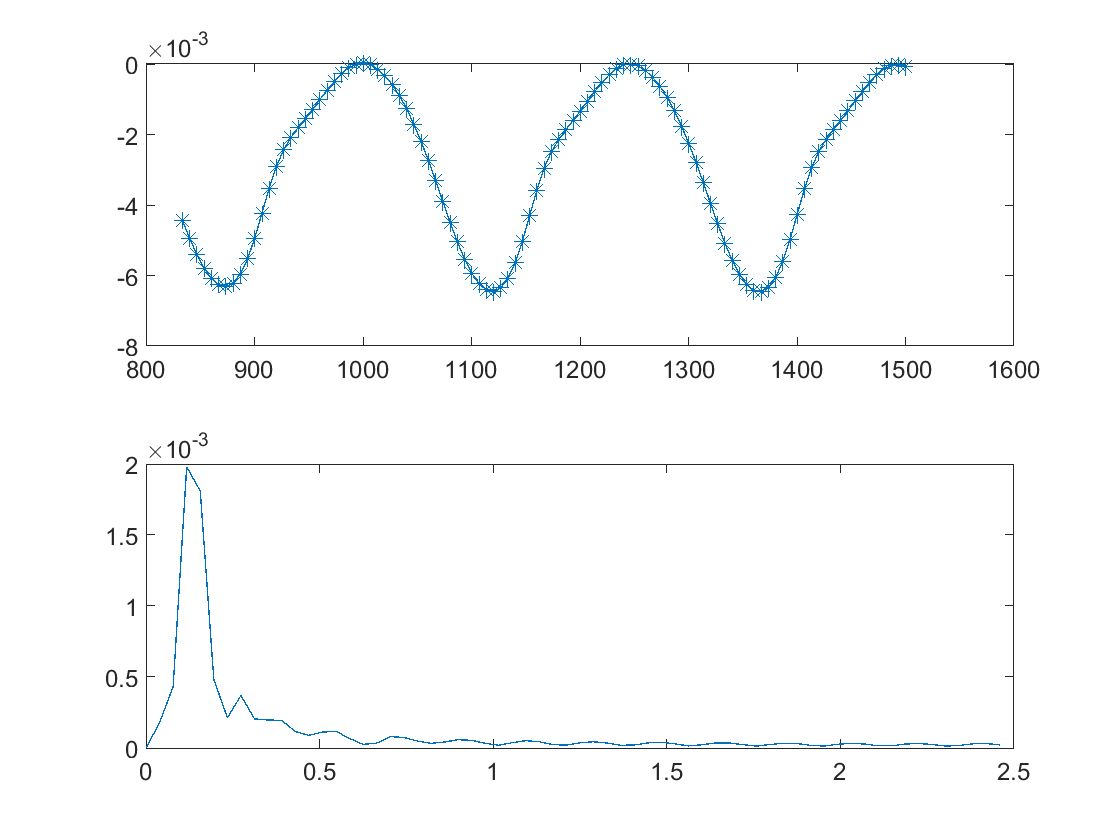


figure
tiledlayout('flow')
nexttile
plot(t2, p(locc, :), 'Marker','*')
nexttile
plot(fff*D_avg/U, AAA)
saveas(gcf, 'time_and_frq_Re_300.svg')


St = f_vs*D_avg/U

St = 0.1172

function [pk, locc, fff, AAA, f_vs] = get_amp(p,fs)
    for i=1:size(p,1)
        temp = p(i,:);
        temp = temp - mean(temp);
        L = length(temp);
        n = 2^nextpow2(L);
        A = fft(temp,n);
        AA(i,:) = abs(A(1:n/2))/(n/2);
        ff(i,:) = fs*(0:n/2-1)/n;
        [pk(i), loc(i)] = max(AA(i,:));
    end
    [~, locc] = max(pk);
    fff = ff(locc,:);
    AAA = AA(locc,:);    
    f_vs = fff(loc(locc));
end



